# Synthèse d'observateur : cas du pendule simple

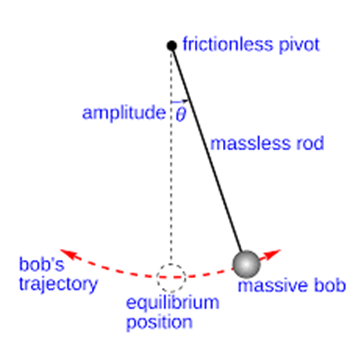

## Objectifs

Concevoir un observateur d'état pour le modèle linéaire du pendule. Utiliser cet observateur pour controller le pendule autour du point d'équilibre.

## Modèles

On considère lle modèle suivant :


$${\textrm{Ml}}^2 \ddot{\;q} +D\dot{q} +\textrm{Mlg}\;\sin \left(q\right)=F\left(t\right)$$


où $q$ est l'angle du pendue et $F$ la force (commande).

% Paramètres :
D=0.1;
m=1;
L=1;
g=10;

## Simulation linéaire :

#### Q : représentation d'état

Donner la représentation d'état linéaire du pendule autour de $q=0$ (position basse). On considère que l'on ne mesure que $q$ i.e. $y=\textrm{Cx}=q$

A = [0 1;
     -g/L -D/(m*L^2)];
B = [0; 
     1/(m*L^2)];
C = [1 0];
D = 0;

#### Q : simulation

Créer un fichier simulink permettant de simuler ce modèle pour les conditions initiales suivante :

q0=deg2rad(10);
dq0=0;

## Observateur d'état

On souhaite réaliser un observateur d'état qui converge en 0.1s.

#### Q : choix pôles observateur

Choisir des pôles permettant d'obtenir ces performances. (*si vous n'avez aucune idée, regardez la méthode par placement de pôles dans le cas de la commande, sinon essayez au hasard et revenez sur la question après*)

% On utilise p = -1/tau
poles_obs = [-3/0.1*(1-1i), -3/0.1*(1+1i)];

#### Q : observateur

Créer un observateur d'état permettant d'estimer la vitesse angulaire $\dot{q}$.

% On conçoit un observateur de Luenberger
Obs = obsv(A, C);
% On vérifie que rank(Obs) = 2
disp("rank(Obs) = ");

rank(Obs) = 


disp(rank(Obs));

     2




L_obs = place(A', C', poles_obs)';
disp("Gain de l'observateur: ");

Gain de l'observateur: 


disp(L_obs);

   1.0e+03 *

    0.0599
    1.7840




A_obs = A - L_obs*C;
C_obs = eye(2);

#### Q : simulation

Comparer le signal de la vitesse angulaire du pendure $\dot{q}$ avec son estimation

## Retour d'état avec observateur

On souahite réaliser un retour d'état pour le pendule permettant de supprimer les oscillations et stabiliser le pendule en 5s.

#### Q : choix pôles commande

Choisir les pôles permettant de réaliser ces performances

poles_cmd = [-3/5*(1-1i), -3/5*(1+1i)];

#### Q : retour d'état

Réaliser un retour d'état se basant sur l'estimation d'état. $u=\textrm{Gr}-K\hat{x}$

% On vérifie la commandabilité
Cmd = ctrb(A, B);
% rank(Cmd) = 2
disp("rank(Cmd) = ");

rank(Cmd) = 


disp(rank(Cmd));

     2




K_cmd = place(A, B, poles_cmd);
disp("Gain du retour d'état: ");

Gain du retour d'état: 


disp(K_cmd);

   -9.2800    1.1000




H_cmd = -pinv(C*(A-B*K_cmd)^(-1)*B);

#### Q : simulation

Simuler le comportement de cette boucle fermée

## Analyse de la boucle fermée

#### Q : analyse sensibilité

Analyser la sensibilité de l'observateur vis-à-vis du bruit de mesure

#### Q : simulation bruit

Illustrer en simulaiton cet effet (utiliser une sinusoide pour le bruit)